[y_noise, Fs_noise] = audioread("sound_sample\noise.wav");

y_noise =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


Fs_noise = 44100

[y_music, Fs_music] = audioread("sound_sample\music_sample.wav");

y_music =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


Fs_music = 44100

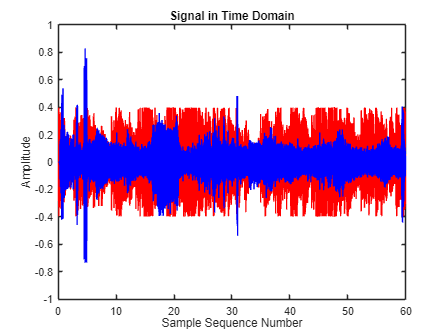

% Plot informations
y_music = y_music*0.4;
y_renoise = y_noise(1:length(y_music),:);

% Mix tape
y_mixture = y_music*0.5 + y_renoise;

plot_numberOfSampler = linspace(0,length(y_music)/Fs_music, length(y_music));
figure;
plot(plot_numberOfSampler, y_music,Color="r");
hold on;
plot(plot_numberOfSampler, y_renoise, Color="b");
hold on;
plot(plot_numberOfSampler, y_mixture, color="gray");
title('Signal in Time Domain')
xlabel('Sample Sequence Number')
ylabel('Amplitude')
ylim([-1,1])

% Audio player
%the_audioPlayer = audioplayer(y_mixture, Fs_music)
sound(y_mixture, Fs_music)
%play(the_audioPlayer)